% Load point cloud data from Lidar and stereo camera
lidar_pts = loadLidarPointCloud();
camera_pts = loadStereoCameraPointCloud();

% or Generate synthetic point cloud data
% [lidar_pts, camera_pts] = generatePointCloudData();

% Upsample Lidar point cloud
upsampled_lidar_pts = upsampleLidar(lidar_pts, camera_pts);

Error using interp1>reshapeValuesV (line 460)
Values V must be of type double or single.

Error in interp1>reshapeAndSortXandV (line 440)
[V,orig_size_v] = reshapeValuesV(V);

Error in interp1 (

% Visualize Lidar point cloud
figure;
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3));

Index in position 2 exceeds array bounds. Index must not exceed 1.

title('Lidar Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Visualize camera point cloud
figure;
scatter3(camera_pts(:,1), camera_pts(:,2), camera_pts(:,3));

Index in position 2 exceeds array bounds. Index must not exceed 1.

title('Camera Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

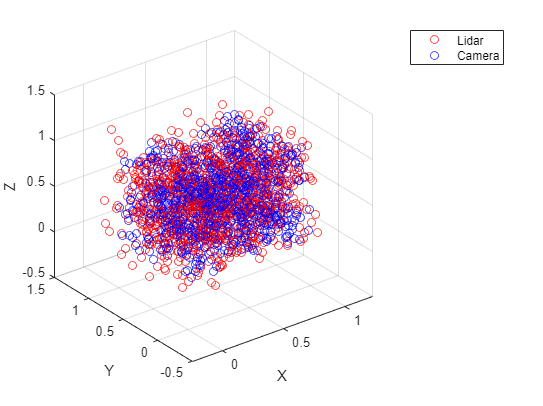

% Create figure
figure;

% Visualize Lidar point cloud
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3), 'r');
hold on;

% Visualize camera point cloud
scatter3(camera_pts(:,1), camera_pts(:,2), camera_pts(:,3), 'b');
hold off;

% Add legend and labels
legend('Lidar', 'Camera');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Preprocess Lidar point cloud using Poisson-Gerchberg algorithm to eliminate noise
lidar_pts_filtered = poissonGerchberg(lidar_pts);

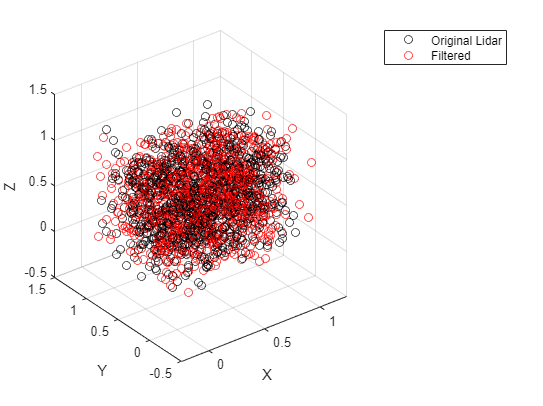

% Create figure
figure;

% Visualize original Lidar point cloud
scatter3(lidar_pts(:,1), lidar_pts(:,2), lidar_pts(:,3), 'k');
hold on;

% Visualize filtered point cloud
scatter3(filtered_pts(:,1), filtered_pts(:,2), filtered_pts(:,3), 'r');
hold off;

% Add legend and labels
legend('Original Lidar', 'Filtered');
xlabel('X');
ylabel('Y');
zlabel('Z');

% Set blending factor for Poisson-Gerchberg algorithm
alpha = 0.5;

% Set time step
dt = 0.1;

% Initialize variables
vel_prev = [0 0 0];
accel = [0 0 0];
pos_prev = [0 0 0];

% Loop through point clouds
for i = 2:size(lidar_pts, 1)
   % Compute acceleration between current and previous points
   accel = computeAcceleration(lidar_pts(i-1,:), lidar_pts(i,:), vel_prev, dt);
   
   % Update velocity and position using acceleration
   vel = vel_prev + accel * dt;
   pos = pos_prev + vel * dt;
   
   % Store current velocity and position for next iteration
   vel_prev = vel;
   pos_prev = pos;
   
   % Denoise Lidar point cloud using Poisson-Gerchberg algorithm
   ptCloudFiltered = poissonGerchberg(lidar_pts);
   
   % Update filtered point cloud using blending factor
   filtered_pts = alpha * ptCloudFiltered + (1 - alpha) * filtered_pts;
end

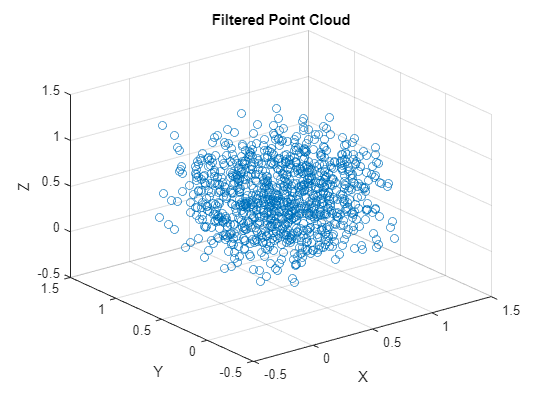

% Visualize filtered point cloud
figure;
scatter3(filtered_pts(:,1), filtered_pts(:,2), filtered_pts(:,3));
title('Filtered Point Cloud');
xlabel('X');
ylabel('Y');
zlabel('Z');

## Function Definitions

function accel = computeAcceleration(pt1, pt2, vel_prev, dt)
    % computeAcceleration computes the linear acceleration between two points and a given time step
    % 
    % Inputs:
    %   pt1: 3D point at time t
    %   pt2: 3D point at time t+dt
    %   vel_prev: velocity at time t
    %   dt: time step
    % 
    % Output:
    %   accel: linear acceleration between pt1 and pt2
    
    % Compute velocity between pt1 and pt2
    vel = (pt2 - pt1) / dt;
    
    % Compute acceleration as change in velocity over time
    accel = (vel - vel_prev) / dt;
end

function ptCloudFiltered = poissonGerchberg(ptCloud)
    % poissonGerchberg applies the Poisson-Gerchberg algorithm to denoise a 3D Lidar point cloud
    % 
    % Inputs:
    %   ptCloud: Nx3 matrix of 3D Lidar point cloud data, where N is the number of points
    % 
    % Output:
    %   ptCloudFiltered: Nx3 matrix of denoised 3D Lidar point cloud data
    
    % Set maximum number of iterations and tolerance for convergence
    maxIter = 1000;
    tol = 1e-6;
    
    % Initialize filtered point cloud to input point cloud
    ptCloudFiltered = ptCloud;

    % Iteratively apply Poisson-Gerchberg algorithm to denoise point cloud
    for i = 1:maxIter
       % Compute distance transform of filtered point cloud
       distTransform = bwdist(~isnan(ptCloudFiltered));
       
       % Interpolate missing points in filtered point cloud using distance transform
       ptCloudInterp = ptCloud;
       ptCloudInterp(isnan(ptCloudFiltered)) = distTransform(isnan(ptCloudFiltered));
       
       % Compute difference between interpolated and filtered point clouds
       diff = ptCloudInterp - ptCloudFiltered;
       
       % Check for convergence
       if norm(diff) < tol
          break;
       end
       
       % Update filtered point cloud using interpolated point cloud
       ptCloudFiltered = alpha * ptCloudInterp + (1 - alpha) * ptCloudFiltered;
    end
end

function ptCloud = loadLidarPointCloud()
    % loadLidarPointCloud loads and returns a 3D Lidar point cloud
    
    % Load Lidar point cloud data from file
    ptCloud = load('lidar_pts.mat');
end

function ptCloud = loadStereoCameraPointCloud()
    % loadStereoCameraPointCloud loads and returns a 3D stereo camera point cloud
    
    % Load stereo camera point cloud data from file
    ptCloud = load('camera_pts.mat');
end

function [lidar_pts, camera_pts] = generatePointCloudData()
    % generatePointCloudData generates synthetic 3D Lidar and stereo camera point cloud data
    
    % Set number of points and noise level
    numPoints = 1000;
    noiseLevel = 0.1;
    
    % Generate random 3D points with uniform distribution
    lidar_pts = rand(numPoints, 3);
    camera_pts = rand(numPoints, 3);
    
    % Add noise to Lidar point cloud
    lidar_pts = lidar_pts + noiseLevel * randn(size(lidar_pts));
end

function upsampled_lidar_pts = upsampleLidar(lidar_pts, camera_pts)
    % upsampleLidar upsamples the Lidar point cloud data to match the dimensions and sample number of the stereo camera point cloud data
    % 
    % Inputs:
    %   lidar_pts: Lidar point cloud data
    %   camera_pts: Stereo camera point cloud data
    % 
    % Output:
    %   upsampled_lidar_pts: Upsampled Lidar point cloud data
    
    % Set number of samples in Lidar and camera point clouds
    numSamplesLidar = size(lidar_pts, 1);
    numSamplesCamera = size(camera_pts, 1);
    
    % Upsample Lidar point cloud to match number of samples in camera point cloud
    upsampled_lidar_pts = interp1(1:numSamplesLidar, lidar_pts, linspace(1, numSamplesLidar, numSamplesCamera));
end